# Mars Rover

### Load the images

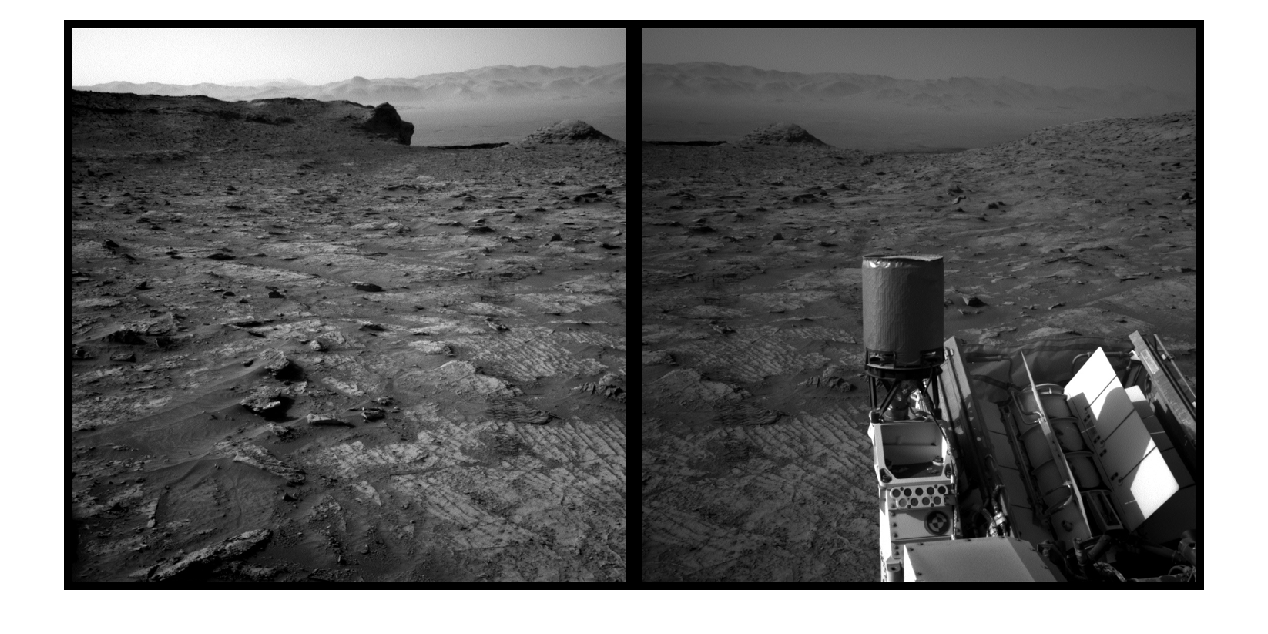

fixedImg = imread("sol_03333_opgs_edr_ncam_NLB_693387385EDR_F0921230NCAM00259M_.JPG");
movingImg = imread("sol_03333_opgs_edr_ncam_NLB_693387301EDR_F0921230NCAM00259M_.JPG");

montage({movingImg, fixedImg},"BorderSize",[10 10])

### Register the Images

Use the Registration Estimator app to create a function that registers the images. Then, use that function to return the registration structure.

When you're happy with your registration function, return to the course and use the online grader to check if it gives the correct result.

reg = registerImages(movingImg, fixedImg);
regImg = reg.RegisteredImage;
disp(fieldnames(reg));

    {'FixedMatchedFeatures' }
    {'MovingMatchedFeatures'}
    {'Transformation'       }
    {'RegisteredImage'      }
    {'SpatialRefObj'        }



### Initialize the Panorama

Use your geometric transformation to determine the world coordinates and initialize an empty panorama image. Here, recall that you're working with **grayscale** images, unlike the color concrete images.

When you're done, return to the course and take the quiz to check if your panorama dimensions are as expected.

tformFixed = projective2d(eye(3));
tformMoving = reg.Transformation;

[hF, wF, ~] = size(fixedImg);
[hM, wM, ~] = size(movingImg);

[xlimF, ylimF] = outputLimits(tformFixed, [1 wF], [1 hF]);
[xlimM, ylimM] = outputLimits(tformMoving, [1 wM], [1 hM]);

xMin = min([xlimF(1) xlimM(1)])

xMin = single
-1.0476e+03

xMax = max([xlimF(2) xlimM(2)])

xMax = single
1024

yMin = min([ylimF(1) ylimM(1)])

yMin = single
-162.3299

yMax = max([ylimF(2) ylimM(2)])

yMax = single
1.3854e+03


width  = round(xMax - xMin + 1)

width = single
2073

height = round(yMax - yMin + 1)

height = single
1549


% Initialize the "empty" panorama.
panorama = zeros([height, width],"uint8");

### Create the Panorama

Use the `vision.AlphaBlender `object to create the final panorama. When you're done, pass your final image to the `testMarsImage` function to see if it's correct. 

If you're correct, go back to the quiz and add the numeric code to complete the course!

If you get a dimension error while using `AlphaBlender`, double check that you are initializing the empty panorama correctly for a grayscale image. Remember that the third dimension of a color image has size 3, but the third dimension of a grayscale image only has size 1.

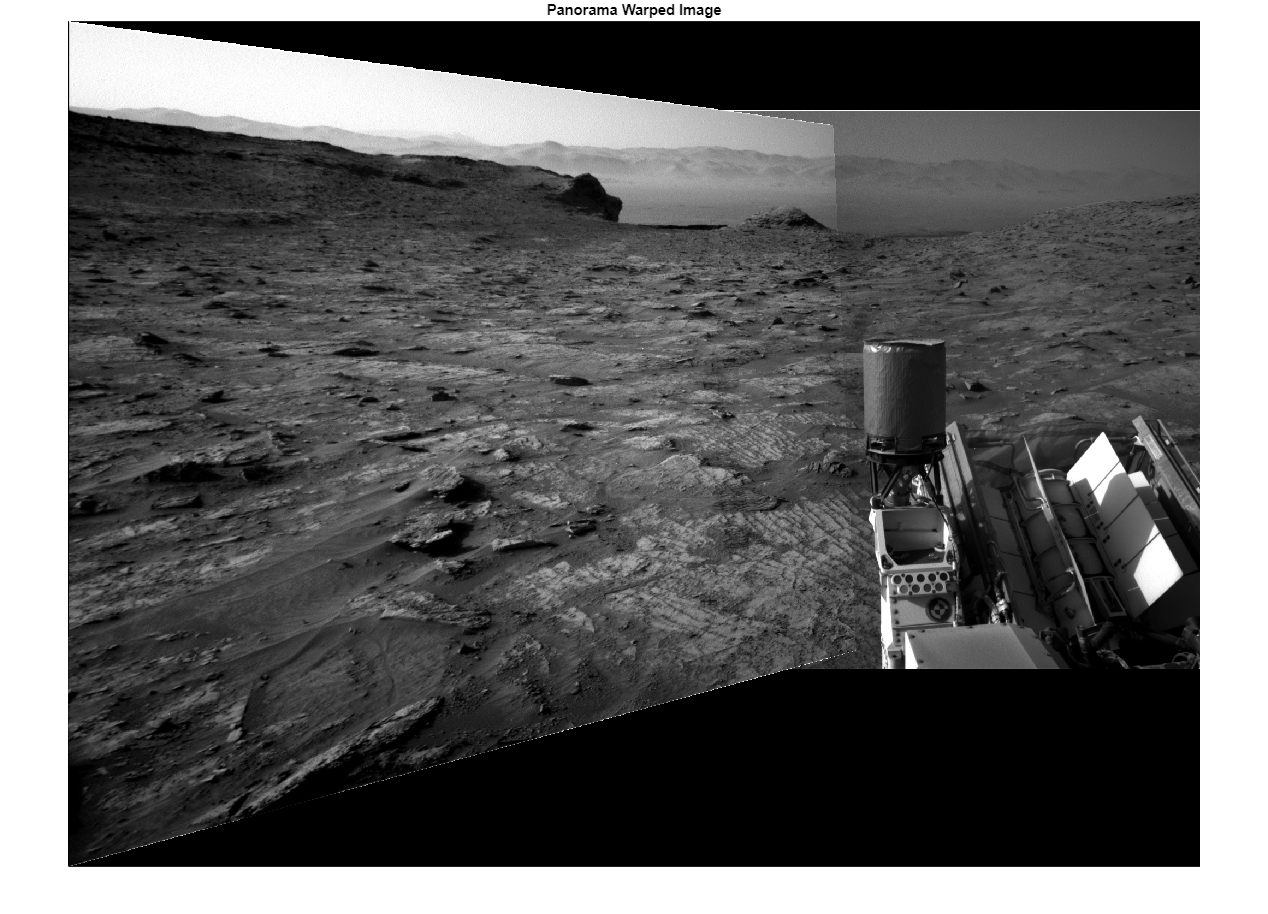

panoramaView = imref2d([height, width], [xMin, xMax], [yMin, yMax]);

warpedFixed  = imwarp(fixedImg, tformFixed,  'OutputView', panoramaView);
warpedMoving = imwarp(movingImg, tformMoving, 'OutputView', panoramaView);

maskFixed  = imwarp(true(size(fixedImg,1),  size(fixedImg,2)),  tformFixed,  'OutputView', panoramaView);
maskMoving = imwarp(true(size(movingImg,1), size(movingImg,2)), tformMoving, 'OutputView', panoramaView);

blender = vision.AlphaBlender("Operation", "Binary mask", "MaskSource", "Input port");

% Composite the fixed image into the panorama.
panorama = step(blender, panorama, warpedFixed, maskFixed);
% Then composite the moving image.
panorama = step(blender, panorama, warpedMoving, maskMoving);

figure;
imshow(panorama);
title('Panorama Warped Image');

testMarsImage(panorama);

Success!
Enter the number: 1984 into the final quiz question.


*Copyright 2022 The MathWorks, Inc.*